# Electric Field Analysis for Wei

## Data preparation in Spike2:

    FIR Filter 

        Band Stop Filter:  HIgh 22 | Low 88 | Transitions Gap 14

    Process

        smooth: time constant 0.005

    Save Channel

    Export as...

        .mat (MatLab-File)

        Channel: 2 Memory (Waveform) % only add Filtered smoothed channel

    add folder with files to MatLab and type in the desiered filename below:

profile on
load('20150802guitar.mat');     % filename for exported Spike2 file
%raw=Analog_In_1_01_Ch2.values; % for 2016 data
raw=V1_GUITAR_01_Ch2.values; % for 2015 data, different instruments

clear Analog*

## Following parameters you can change:

sample_rate=5500;       % default 5500 (Wei 2016)
beginning_sec=1;        % start of plot in seconds
ending_sec=347;         % end of plot in seconds
waggle_threshold=12;    % amount of symetry build up as waggle indicator, default 12
waggle_frequenzy=33;    % cut of frequency in Hz, below will be concidered waggle

## Code:

[pks, pks_locs] = findpeaks(raw);                 
peakInterval = diff(pks_locs);

n=0;
triangles=zeros(length(peakInterval),1);
for i=1:length(peakInterval)-10
    delta=abs(peakInterval(i)-peakInterval(i+1));
if delta<20   % amount of datapoints (~3,5ms)
   n=n+3; 
elseif delta<40
   n=n+2;
elseif delta<60
   n=n+1;    
else
    n=0;
end  
    triangles(i)=n;
end

%triangles_full=zeros(length(raw),1);
%triangles_full(pks_locs(1:length(pks_locs)-1))=triangles; 
%peakInterval_full=zeros(length(raw),1);
%peakInterval_full(pks_locs(1:length(pks_locs)-1))=peakInterval;  
%time_sec=1:1:length(raw);
%time_sec=(time_sec/sample_rate)';
%peakInterval_full(peakInterval_full==0)=nan;
%triangles_full(triangles_full<4)=nan;


beginning=beginning_sec*sample_rate;
ending=ending_sec*sample_rate;
% plot(time_sec(beginning:ending),triangles_full(beginning:ending))
% hold on
% plot(time_sec(beginning:ending),raw(beginning:ending))
% plot(time_sec(beginning:ending),raw(beginning:ending)*10000);
% hold on
% plot(time_sec(beginning:ending),peakInterval_full(beginning:ending),'*');
% plot(time_sec(beginning:ending),triangles_full(beginning:ending)*100,'o','MarkerFaceColor','G');
% hold off
eventTable=zeros(length(triangles),9);
%  1 value max and 1 as start
%  2 locs start
%  3 locs stop
%  4 main frequency
%  5 start in seconds
%  6 stop in seconds
%  7 duration in seconds
%  8 main amplitude
%  9 Nr waggles
a=1;
for i = 1:length(triangles)-1
    if triangles(i)>triangles(i+1)  && triangles(i)>waggle_threshold
        eventTable(a,1)=triangles(i);
        eventTable(a,3)=pks_locs(i);        
        j=1;
        n=0;
        while n==0
            if i-j==0
                return
            end
              if triangles(i-j)==0
                  n=1;
                  eventTable(a,2)=pks_locs(i-j);
              end
        j=j+1;
        end
        eventTable(a,9)=j;
        a=a+1;
    end  
end


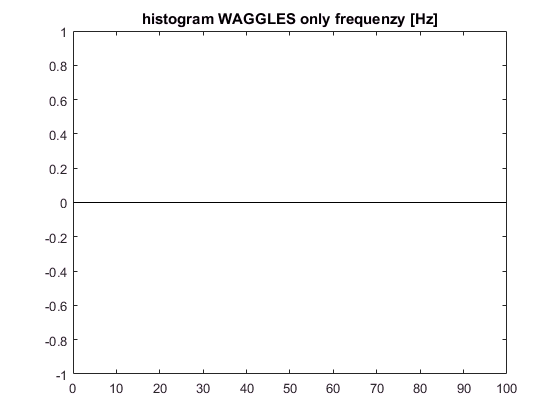

eventTable2(:,:)=eventTable(1:a,:);
eventTable=eventTable2;
clear eventTable2;
eventTable(:,4)=5500*eventTable(:,9)./(eventTable(:,3)-eventTable(:,2));
eventTable(:,5)=eventTable(:,2)/5500;
eventTable(:,6)=eventTable(:,3)/5500;
eventTable(:,7)=eventTable(:,6)-eventTable(:,5);
eventTable=eventTable(1:end-1,:);

for i=1:length(eventTable)    %amplitude
eventTable(i,8)=max(raw(eventTable(i,2):eventTable(i,2)+floor(5500/eventTable(i,4))))...
    -min(raw(eventTable(i,2):eventTable(i,2)+floor(5500/eventTable(i,4))));
end

eventTable_sort=sortrows(eventTable,4);
eventTable_waggle=eventTable(eventTable(:,4)<waggle_frequenzy,:);
k=1;
 for k=1:5:floor(length(eventTable_waggle)/6)
    figure
    for i=1:6
        subplot(3,2,i)
        plot(raw(eventTable_waggle(k*i,2):eventTable_waggle(k*i,3)));
    end
end

figure
histogram(eventTable_waggle(:,4),100)
title('histogram WAGGLES only frequenzy [Hz]')

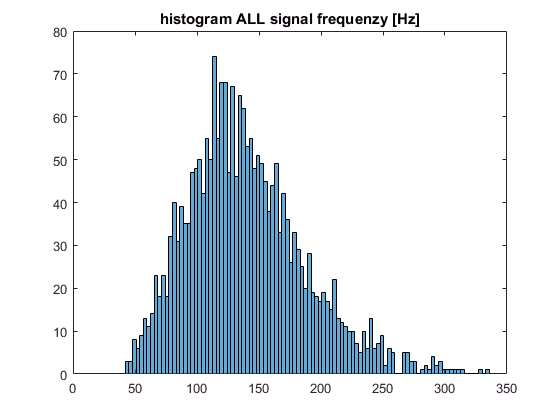

figure
histogram(eventTable(:,4),100)
title('histogram ALL signal frequenzy [Hz]')

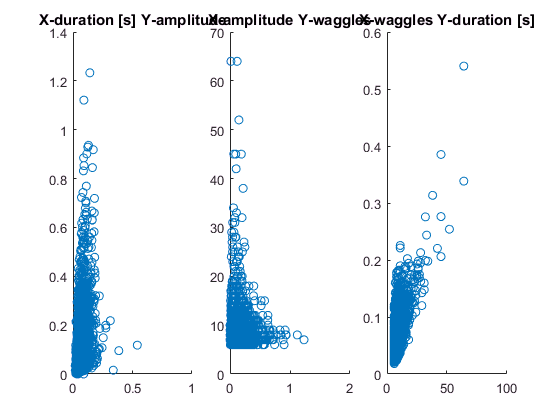


figure
subplot(1,3,1)
plot(eventTable_waggle(:,7),eventTable_waggle(:,8),'*')
hold on
plot(eventTable(:,7),eventTable(:,8),'o')
title('X-duration [s] Y-amplitude')
subplot(1,3,2)
plot(eventTable_waggle(:,8),eventTable_waggle(:,9),'*')
hold on
plot(eventTable(:,8),eventTable(:,9),'o')
title('X-amplitude Y-waggles')
subplot(1,3,3)
plot(eventTable_waggle(:,9),eventTable_waggle(:,7),'*')
hold on
plot(eventTable(:,9),eventTable(:,7),'o')
title('X-waggles Y-duration [s]')

profile viewer

## Results / Output

**eventTable**:

 1 value max and 1 as start (internal, please ignore)

 2 locs start (datapint wise, so 5500 datapints per second)

 3 locs stop

 4 main frequency [Hz]

 5 start in seconds

 6 stop in seconds

 7 duration in seconds

 8 main amplitude 

 9 Nr waggles

the table **eventTable_waggle **only contains waggles/signals below the waggle_frequency (default 33Hz). 

if exist(eventTable_waggle) == 1
filename1 = 'eventTable_waggle.xlsx';
xlswrite(filename1,eventTable_waggle)
end

filename2 = 'eventTable.xlsx';
xlswrite(filename2,eventTable)